# EECS 965 Homework 04                                 William Powers 2025

#### ***1. Determine the correct threshold ***$y\prime$* for a decision rule of the form:*  Choose  $H_1$  if  $T_d = x > y\prime$ 

Given hypothesis $H_0$ describes the single random variable $w_1$ which is exponentially distributed, the likelihood of this hypothesis producing measurement $x$ can be written directly as


$$p(x|H_0)= \lambda_1 e^{-\lambda_1x}$$


Hypothesis $H_1$ describes the measurement being the sum of two independent exponentially distributed random variables $w_1$ and $w_2$. The resulting likelihood distribution of $H_1$ producing this measurement is the convolution of the individual exponential distributions which, using [1], is

$p(x|H_1) = \frac{\lambda_1 \lambda_2}{\lambda_2 - \lambda_1} \left(  e^{-\lambda_i x} - e^{-\lambda_2 x}\right)$  with  $\lambda_1 \ne \lambda_2$

Given the two hypotheses $H_0 = w_1$ and $H_1 = w_1 + w_2$ are equally probable, there a posteriori probabilities are desribed as


$$p(H_0|x) = \frac{p(x|H_0)p(H_0)}{p(x|H_0)p(H__0) + p(x|H_1)p(H_1)}$$



$$p(H_1|x) = \frac{p(x|H_1)p(H_1)}{p(x|H_0)p(H__0) + p(x|H_1)p(H_1)}$$


From this a posteriori expression, the decision rule for $H_1$ is thus written as

Choose  $H_1$  if  $p(H_1|x) > p(H_0|x)$

Dividing the entire rule by $p(H_0|x)$, noting that each a posteriori probability is equal to its liklihood probability of that hypothesis, frames the liklihood ratio test

Choose  $H_1$ if  $\frac{p(H_1|x)}{p(H_0|x)} =L(x)> 1.0$

To determine this liklihood ratio in terms of the detection statistic $T_d(x)$, simplifications of $L(x)$ are required. First, recongnizing that the denominators of both a posteriori distributions are the equal, these denominators are cancelled. This leaves the liklihood ratio


$$L(x) = \frac{p(x|H_1)}{p(x|H_0)|} = \frac{ \frac{\lambda_1 \lambda_2}{\lambda_2 - \lambda_1} \left(  e^{-\lambda_i x} - e^{-\lambda_2 x}\right)}{\lambda_1 e^{-\lambda_1x}} = 

\frac{\lambda_2}{\lambda_2 - \lambda_1} \left( 1 - e^{-(\lambda_2 - \lambda_1)x} \right)$$


Moving the scalar to the left handside of the inequality and taking the natural log of both sides leaves


$$-(\lambda_2 - \lambda_1)x > \ln \left( \frac{\lambda_1}{\lambda_2} \right)$$


Solving for $x$ leaves the detection statistic $T_d(x) = x$ on the left side of the equation and an equivalently scaled decision boundary on the right.

if    $(\lambda_2  - \lambda_1) > 0$    $\rightarrow$    Choose $H_1$  if  $T_d(x) = x > \frac{\ln (\lambda_2 / \lambda_1)}{\lambda_2 - \lambda_1}$

if    $(\lambda_2 - \lambda_1) < 0$    $\rightarrow$    Choose  $H_1$  if  $T_d(x) = x < \frac{\ln (\lambda_2 / \lambda_1)}{\lambda_2 - \lambda_1}$

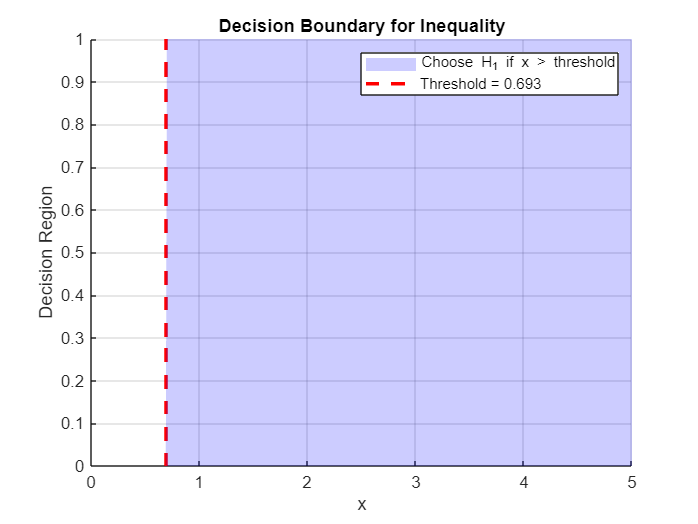

% exponential lambda values
lambda1 = 1;
lambda2 = 2;

% compute detection statistic threshold
threshold = log(lambda2/lambda1) / (lambda2 - lambda1);

% determine decision region depending on sign of (lambda2 - lambda1)
x = linspace(0, 5, 500);
if lambda2 > lambda1
    decisionRegion = (x > threshold);
else
    decisionRegion = (x < threshold);
end

% plot results
figure; hold on; grid on;
plot([threshold threshold], [0 1], 'r--', 'LineWidth', 2);
area(x, decisionRegion, 'FaceAlpha', 0.2, 'FaceColor', 'b', 'EdgeColor', 'none');
xlabel('x'); ylabel('Decision Region');
title('Decision Boundary for Inequality');
if lambda2 > lambda1
    legend(sprintf('Threshold = %.3f', threshold), 'Choose H_1 if x > threshold');
else
    legend(sprintf('Threshold = %.3f', threshold), 'Choose H_1 if x < threshold');
end

[1] [https://en.wikipedia.org/wiki/Exponential_distribution](https://en.wikipedia.org/wiki/Exponential_distribution)